## Water level vs. Evaporation rates

Questions/Steps

- Load data

- Look at period that there are Eddy Cov evaporation rates for

- Estimate recharge from that rain event.

#### Evap and Weater Data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses'
cd Groundwater\SpecificYieldEstimation\data\input\
load('Bflat30min.mat')
load('bflatDaily_Evap.mat')

#### Water Level

load("BLM93_ThermEff.mat");
BLM93therm = BLM93;
load('BLM93C_ThermEff.mat');
BLM93Ctherm = BLM93C;
load("BLM93_AirPresCor.mat")
load("BLM93C_AirPresCor.mat")

BLM93C = removevars(BLM93C, {'AirTemp1_C','SoilTemp_C','NetRad_Wm2','AirTemp2_C','RelHumidity','WindSpeed_kph','WindDirection_Degrees','WindGust_kph','PPT_mm','NetRad_sw_Wm2','SolarRad_Wm2','NetRad_lw_Wm2','OutRad_sw_Wm2','OutRad_lw_Wm2','InRad_lw_Wm2'});
BLM93 = removevars(BLM93, {'AirTemp1_C','SoilTemp_C'});
BLM93Ctherm = removevars(BLM93Ctherm, {'NetRad_Wm2','AirTemp1_C','AirTemp2_C','RelHumidity','WindSpeed_kph','WindDirection_Degrees','WindGust_kph','PPT_mm','NetRad_sw_Wm2','SolarRad_Wm2','SoilTemp_C','NetRad_lw_Wm2','OutRad_sw_Wm2','OutRad_lw_Wm2','InRad_lw_Wm2','timeMDT'});
BLM93therm = removevars(BLM93therm, {'AirTemp1_C','SoilTemp_C'});

BLM93daily = retime(BLM93, "daily", 'mean');
BLM93Cdaily = retime(BLM93C, "daily", 'mean');
BflatDaily93 = outerjoin(BflatDaily,BLM93daily,'Type','left');
BflatDaily93C = outerjoin(BflatDaily,BLM93Cdaily,'Type','left');

BflatDaily93Therm = outerjoin(BflatDaily,BLM93therm,'Type','left');
BflatDaily93CTherm = outerjoin(BflatDaily,BLM93Ctherm,'Type','left');

## May 10 to May 17 2018 rain - surface ponding - surface already wet 

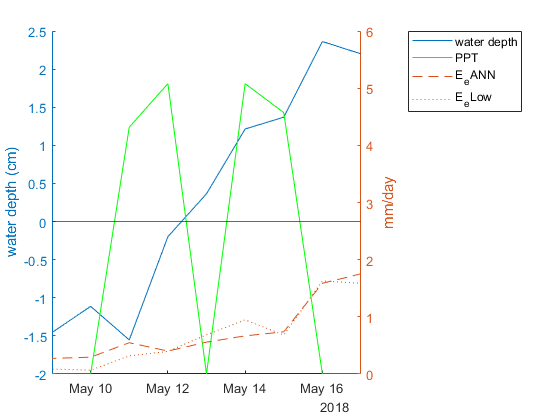

SpecificYield = 1×14 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN    SyEeLow
    _________    _______    __________    _______    _______    __________________    _________________    _______________    ____    _____________    _____________    _______________    _______    _______

       588         596        19.05       6.8184     6.3939           36.554        

xlimit = [588,596];
SpecificYield(1, :) = PlotDTWRain(xlimit, BflatDaily93, 93)

## July 16 to July 18, 2018. 

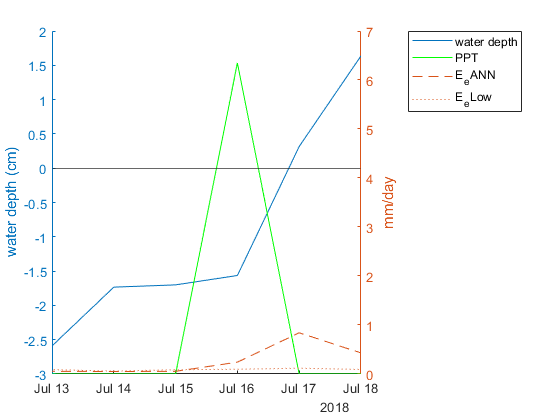

SpecificYield = 2×14 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN    SyEeLow
    _________    _______    __________    _______    _______    __________________    _________________    _______________    ____    _____________    _____________    _______________    _______    _______

       588         596        19.05       6.8184      6.3939          36.554        

xlimit = [653,658];
SpecificYield(2, :) = PlotDTWRain(xlimit, BflatDaily93, 93)

## October 2 - Oct 7,  2018 rain (lower specific yield)

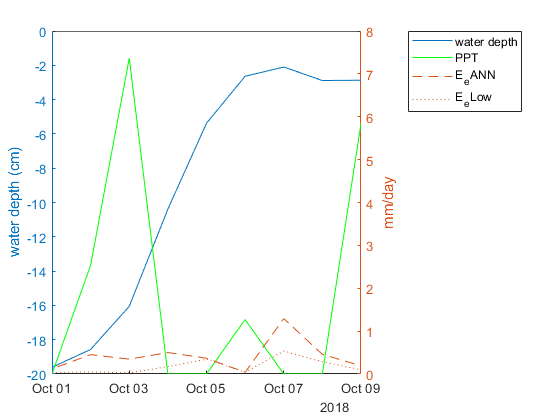

SpecificYield = 3×14 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    _______    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05      6.8184      6.3939          36.554    

xlimit = [733,741];
SpecificYield(3, :) = PlotDTWRain(xlimit, BflatDaily93, 93)

## November 21-Dec 5, 2018 rain

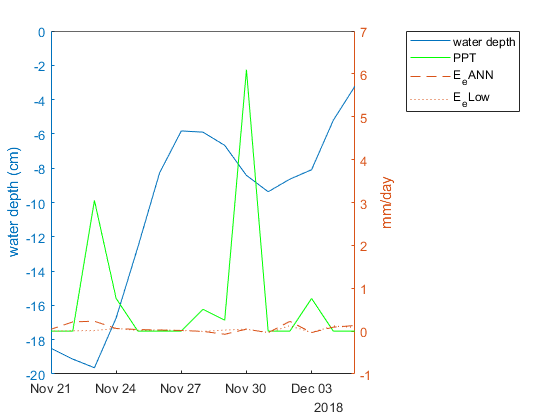

SpecificYield = 4×14 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    _______    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05       6.8184     6.3939          36.554    

xlimit = [784,798];
SpecificYield(4, :) = PlotDTWRain(xlimit, BflatDaily93, 93)

## April 14-28, 2019 rain - Water level above surface 2-10 cm

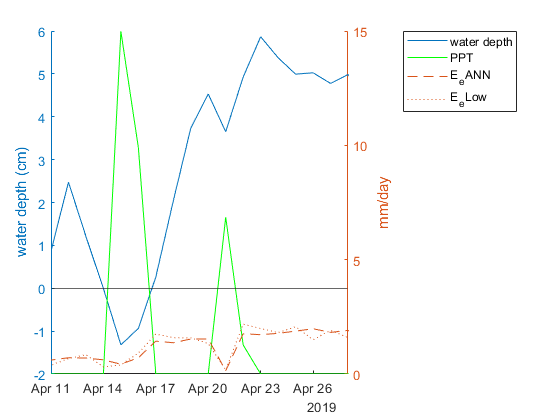

SpecificYield = 5×14 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    _______    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05       6.8184     6.3939          36.554    

xlimit = [925,942];
SpecificYield(5, :) = PlotDTWRain(xlimit, BflatDaily93, 93)

## August 8-10, 2019 rain - dry surface 

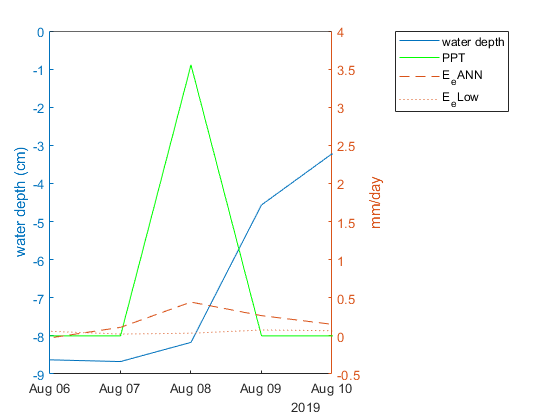

SpecificYield = 6×14 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    _______    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05       6.8184     6.3939          36.554    

xlimit = [1042,1046];
SpecificYield(6, :) = PlotDTWRain(xlimit, BflatDaily93, 93)

## September 27 - Oct 1 2019 rain - 93C

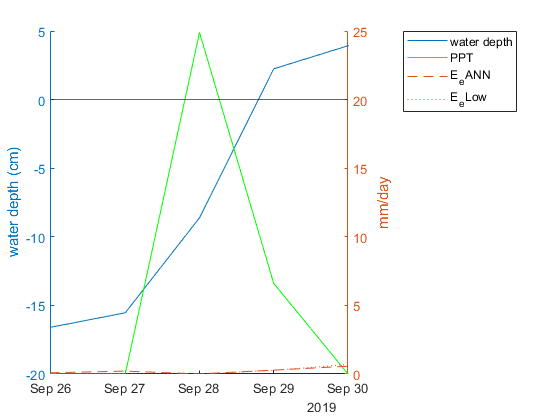

SpecificYield = 7×14 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    _______    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05       6.8184     6.3939          36.554    

xlimit = [1093,1097];
SpecificYield(7, :) = PlotDTWRain(xlimit, BflatDaily93C, 93.3)

## November 2019-December 15, 2019

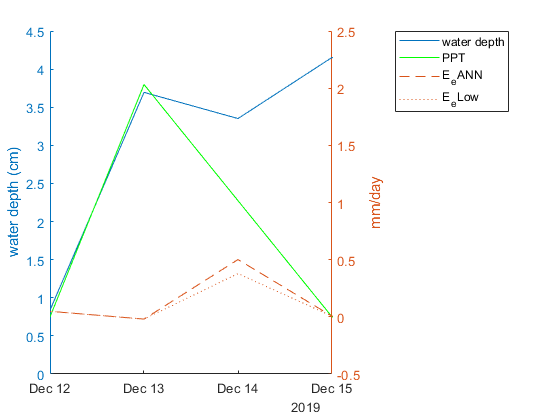

SpecificYield = 8×14 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    _______    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05       6.8184     6.3939          36.554    

xlimit = [1170,1173];
SpecificYield(8, :) = PlotDTWRain(xlimit, BflatDaily93C, 93.3)

## June 2020

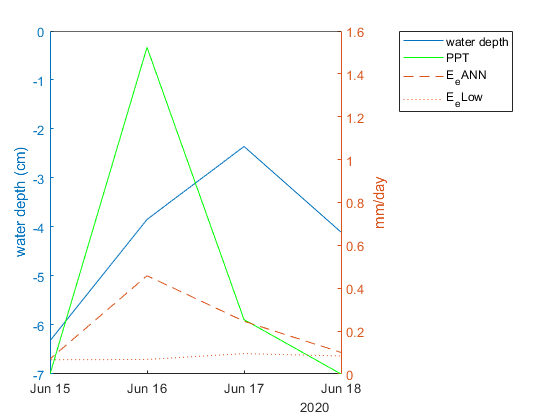

SpecificYield = 9×14 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    _______    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05       6.8184     6.3939          36.554    

xlimit = [1356,1359];
SpecificYield(9, :) = PlotDTWRain(xlimit, BflatDaily93C, 93.3)

## July 27-28, 2020 rain - more evap than rain, and only a small increase in water level..

## Other Small rain events in 2020 were all too small to influence water level

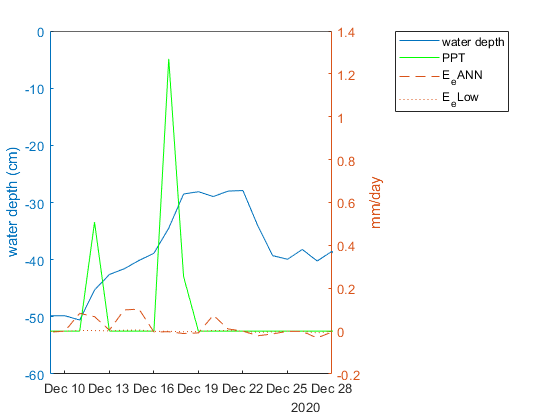

SpecificYield = 10×14 table
    startdate    enddate    TotalPPTmm    EeLowmm     EeANNmm      WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    __________    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05       6.8184        6.3939          


%Dec 9 2020 to Dec 22/28
xlimit = [1533,1552];
SpecificYield(10, :) = PlotDTWRain(xlimit, BflatDaily93C, 93.3)

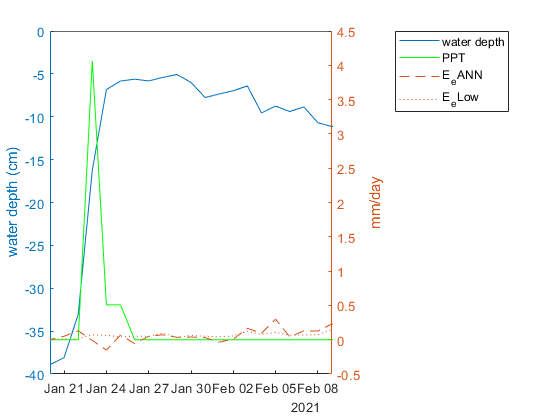

SpecificYield = 11×14 table
    startdate    enddate    TotalPPTmm    EeLowmm     EeANNmm      WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    __________    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05       6.8184        6.3939          

%Jan 20 2021 to Feb 9 2021
xlimit = [1575,1595];
SpecificYield(11, :) = PlotDTWRain(xlimit, BflatDaily93C, 93.3)

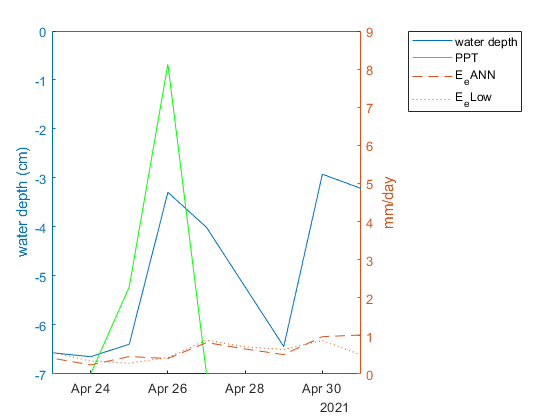

SpecificYield = 12×14 table
    startdate    enddate    TotalPPTmm    EeLowmm     EeANNmm      WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    __________    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05       6.8184        6.3939          

%April 23 to May 1st
xlimit = [1668,1676];
SpecificYield(12, :) = PlotDTWRain(xlimit, BflatDaily93C, 93.3)

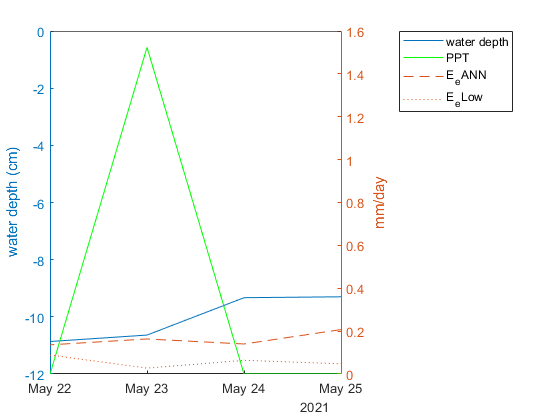

SpecificYield = 13×14 table
    startdate    enddate    TotalPPTmm    EeLowmm     EeANNmm      WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent    SyEeANN     SyEeLow 
    _________    _______    __________    _______    __________    __________________    _________________    _______________    ____    _____________    _____________    _______________    ________    ________

       588         596         19.05       6.8184        6.3939          

%May 22 to May 31
xlimit = [1697,1700];
SpecificYield(13, :) = PlotDTWRain(xlimit, BflatDaily93C, 93.3)

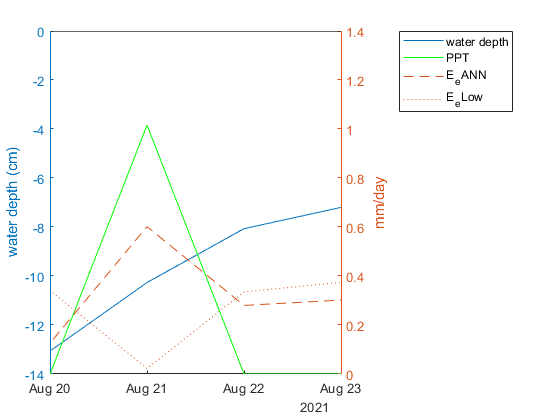

SpecificYield = 14×14 table
    startdate    enddate    TotalPPTmm    EeLowmm     EeANNmm      WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    RechargeEeANN    RechargeEeLow    RechargePercent     SyEeANN        SyEeLow  
    _________    _______    __________    _______    __________    __________________    _________________    _______________    ____    _____________    _____________    _______________    __________    ___________

       588         596         19.05       6.8184        6.3939

%Aug 19 to Aug 27th 
xlimit = [1787,1790];
SpecificYield(14, :) = PlotDTWRain(xlimit, BflatDaily93C, 93.3)

## Screen out and visualize specific yield values

SpecificYield = SpecificYield(SpecificYield.SyEeLow < 0.20, :);
SpecificYield = SpecificYield(SpecificYield.SyEeLow > 0.03, :);
BLM93Csy = mean(mean([SpecificYield.SyEeLow SpecificYield.SyEeANN]))

BLM93Csy = 0.0926

BLM93CsySTD = mean(std([SpecificYield.SyEeLow SpecificYield.SyEeANN]))

BLM93CsySTD = 0.0386

%No strong relationship between Sy and water depth after extremes excluded
%(winter with very low (>20 cm) water depth, and near flooded surface.)
[fitting, error] = fit(SpecificYield.StartWaterDepthmm, SpecificYield.SyEeLow, 'poly1')

fitting =      Linear model Poly1:
     fitting(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =  -1.788e-05  (-0.0004804, 0.0004446)
       p2 =       0.101  (0.04575, 0.1563)

error = struct with fields:
           sse: 0.0109
       rsquare: 0.0012
           dfe: 7
    adjrsquare: -0.1415
          rmse: 0.0395


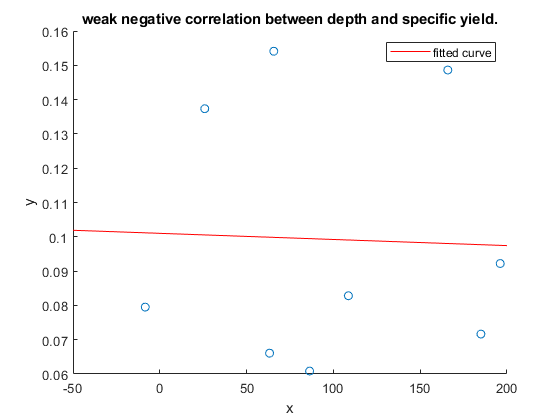


figure
hold on 
scatter(SpecificYield.StartWaterDepthmm, SpecificYield.SyEeLow)
plot(fitting)
title('weak negative correlation between depth and specific yield.')

# Use specifc yield and thermally corrected water level change during periods of pumping to estimate evaporation rates

## March 4- March 18, 2020  - water level fall contrast evaporation methods

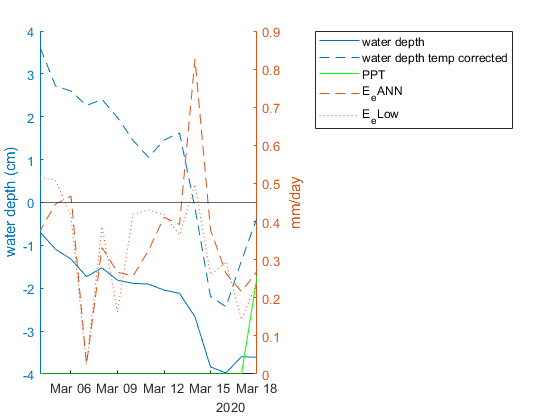

EeBFLATvsEeDdtw = 1×21 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    NetEeANN    NetEeLow    EeANNDaily    EeSyDaily    EeSyDailyThermCor    WaterLevelChangeThermCormm    EeSyDdtwConst    EeSyDdtwTherm    EeSyDdtwConstPlsStd    EeSyDdtwConstMnsStd    EeSyDdtwThermPlsStd    EeSyDdtwThermMnsStd
    _________    _______    __________    _______    _______    __________________    _________________    _______________

xlimit = [1253,1267];
EeBFLATvsEeDdtw(1, :) = PlotDTWRainThermal(xlimit, BflatDaily93CTherm, 93.3, BLM93Csy, BLM93CsySTD)

% xlimit = [1098,1110];
% EeBFLATvsEeDdtw(2, :) = PlotDTWRainThermal(xlimit, BflatDaily93CTherm, 93.3, BLM93Csy, BLM93CsySTD)

### July to sept 2020 - does a good job of replicating

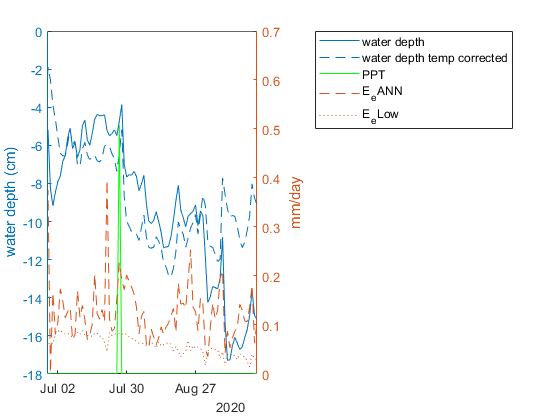

EeBFLATvsEeDdtw = 2×21 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    NetEeANN    NetEeLow    EeANNDaily    EeSyDaily    EeSyDailyThermCor    WaterLevelChangeThermCormm    EeSyDdtwConst    EeSyDdtwTherm    EeSyDdtwConstPlsStd    EeSyDdtwConstMnsStd    EeSyDdtwThermPlsStd    EeSyDdtwThermMnsStd
    _________    _______    __________    _______    _______    __________________    _________________    _______________

xlimit = [1369,1454];
EeBFLATvsEeDdtw(2, :) = PlotDTWRainThermal(xlimit, BflatDaily93CTherm, 93.3, BLM93Csy, BLM93CsySTD)

## March 4- April 21, 2020  - water level fall contrast evaporation methods

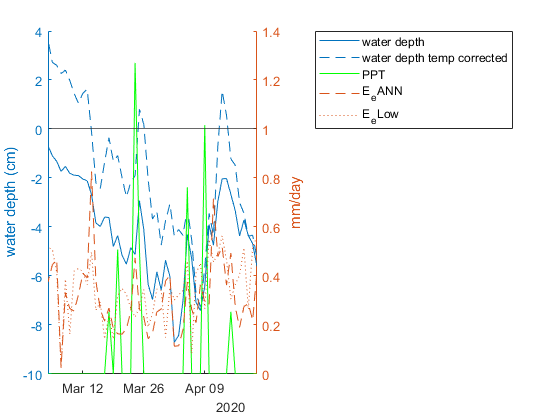

EeBFLATvsEeDdtw = 3×21 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    NetEeANN    NetEeLow    EeANNDaily    EeSyDaily    EeSyDailyThermCor    WaterLevelChangeThermCormm    EeSyDdtwConst    EeSyDdtwTherm    EeSyDdtwConstPlsStd    EeSyDdtwConstMnsStd    EeSyDdtwThermPlsStd    EeSyDdtwThermMnsStd
    _________    _______    __________    _______    _______    __________________    _________________    _______________

xlimit = [1253,1301];
EeBFLATvsEeDdtw(3, :) = PlotDTWRainThermal(xlimit, BflatDaily93CTherm, 93.3, BLM93Csy, BLM93CsySTD)

## June 20- Aug 11, 2021  - water level fall contrast evaporation methods

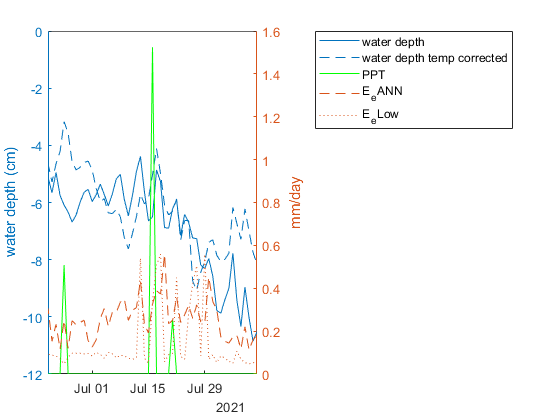

EeBFLATvsEeDdtw = 4×21 table
    startdate    enddate    TotalPPTmm    EeLowmm    EeANNmm    WaterLevelChangemm    StartWaterDepthmm    SoilTempChangeC    well    NetEeANN    NetEeLow    EeANNDaily    EeSyDaily    EeSyDailyThermCor    WaterLevelChangeThermCormm    EeSyDdtwConst    EeSyDdtwTherm    EeSyDdtwConstPlsStd    EeSyDdtwConstMnsStd    EeSyDdtwThermPlsStd    EeSyDdtwThermMnsStd
    _________    _______    __________    _______    _______    __________________    _________________    _______________

xlimit = [1726,1778];
EeBFLATvsEeDdtw(4, :) = PlotDTWRainThermal(xlimit, BflatDaily93CTherm, 93.3, BLM93Csy, BLM93CsySTD)

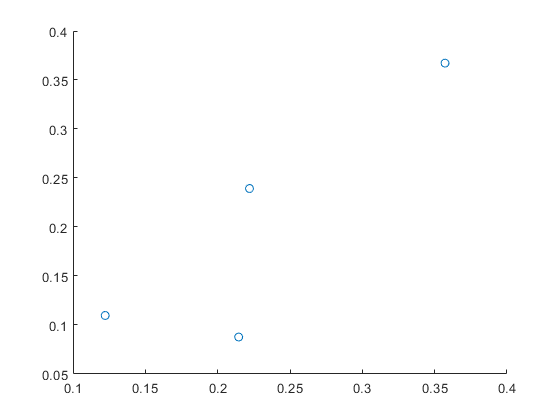

figure
scatter(EeBFLATvsEeDdtw.EeANNDaily, EeBFLATvsEeDdtw.EeSyDailyThermCor)

### Estimate of seasonal evaporation

waterDrawDown = 5; % low end drawdown (cm)
NetEvaporation = waterDrawDown*BLM93Csy*10 % decrease in water volume in mm

NetEvaporation = 6.4598

daysofEvaporation = 50;  % days of evaporation June 28 to September 23rd 
NetEvaporation/daysofEvaporation

ans = 0.1292


waterDrawDown = 10; % high end drawdown (cm)
NetEvaporation = waterDrawDown*BLM93Csy*10 % decrease in water volume in mm

NetEvaporation = 12.9196

daysofEvaporation = 50;  % days of evaporation June 28 to September 23rd 
NetEvaporation/daysofEvaporation

ans = 0.2584

cd ..\output\
save('SpecificYield.mat', 'SpecificYield')
save('SyEvaporationTest', 'EeBFLATvsEeDdtw')

function results = PlotDTWRain(xlimit, BflatDaily, well)

figure

hold on
yyaxis left
plot(BflatDaily.Date_Time_MDT, BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,'displayname', 'water depth')
yline(0, 'handlevisibility', 'off');
ylabel('water depth (cm)')

yyaxis right
hold on 
plot(BflatDaily.Date_Time_MDT, BflatDaily.PPT_mm,'color', 'green', 'displayname', 'PPT')
plot(BflatDaily.Date_Time_MDT, BflatDaily.LEann_prctile50_modified, 'displayname', 'E_eANN')
plot(BflatDaily.Date_Time_MDT, BflatDaily.PET_m_CN_albedoPiecewise, 'displayname', 'E_eLow')
ylabel('mm/day')

xlim(BflatDaily.Date_Time_MDT([xlimit]))
legend('location', "bestoutside")

results(1) = xlimit(1);
results(2) = xlimit(2);
results(3) = sum(BflatDaily.PPT_mm(xlimit(1):xlimit(2)));
results(4) = sum(BflatDaily.LEann_prctile50_modified(xlimit(1):xlimit(2)));
results(5) = sum(BflatDaily.PET_m_CN_albedoPiecewise(xlimit(1):xlimit(2)));
results(6) = (BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor(xlimit(1)) - BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor(xlimit(2)))*1000;
results(7) = (BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor(xlimit(1)))*1000;
results(8) = -(BflatDaily.SoilTemp_C(xlimit(1)) - BflatDaily.SoilTemp_C(xlimit(2)));
results(9) = well;

results(10) = results(3) - results(4);
results(11) = results(3) - results(5);
results(12) = mean([results(10)/results(3) results(10)/results(3)])*100;
results(13) = results(10)/results(6);
results(14) = results(11)/results(6);

results = array2table(results);
results.Properties.VariableNames{1} = 'startdate';
results.Properties.VariableNames{2} = 'enddate';
results.Properties.VariableNames{3} = 'TotalPPTmm';
results.Properties.VariableNames{4} = 'EeLowmm';
results.Properties.VariableNames{5} = 'EeANNmm';
results.Properties.VariableNames{6} = 'WaterLevelChangemm';
results.Properties.VariableNames{7} = 'StartWaterDepthmm';
results.Properties.VariableNames{8} = 'SoilTempChangeC';
results.Properties.VariableNames{9} = 'well';
results.Properties.VariableNames{10} = 'RechargeEeANN';
results.Properties.VariableNames{11} = 'RechargeEeLow';
results.Properties.VariableNames{12} = 'RechargePercent';
results.Properties.VariableNames{13} = 'SyEeANN';
results.Properties.VariableNames{14} = 'SyEeLow';
end

function results = PlotDTWRainThermal(xlimit, BflatDaily, well, Sy, SyStd)

figure

hold on
yyaxis left
plot(BflatDaily.Date_Time_MDT, BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,'displayname', 'water depth')
plot(BflatDaily.Date_Time_MDT, BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_ThermCo*-100,'displayname', 'water depth temp corrected')

yline(0, 'handlevisibility', 'off');
ylabel('water depth (cm)')

yyaxis right
hold on 
plot(BflatDaily.Date_Time_MDT, BflatDaily.PPT_mm,'color', 'green', 'displayname', 'PPT')
plot(BflatDaily.Date_Time_MDT, BflatDaily.LEann_prctile50_modified, 'displayname', 'E_eANN')
plot(BflatDaily.Date_Time_MDT, BflatDaily.PET_m_CN_albedoPiecewise, 'displayname', 'E_eLow')
ylabel('mm/day')

xlim(BflatDaily.Date_Time_MDT([xlimit]))
legend('location', "bestoutside")

results(1) = xlimit(1);
results(2) = xlimit(2);
results(3) = sum(BflatDaily.PPT_mm(xlimit(1):xlimit(2)));
results(4) = sum(BflatDaily.LEann_prctile50_modified(xlimit(1):xlimit(2)));
results(5) = sum(BflatDaily.PET_m_CN_albedoPiecewise(xlimit(1):xlimit(2)));
results(6) = (BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor(xlimit(1)) - BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor(xlimit(2)))*1000;
results(7) = (BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor(xlimit(1)))*1000;
results(8) = -(BflatDaily.SoilTemp_C(xlimit(1)) - BflatDaily.SoilTemp_C(xlimit(2)));
results(9) = well;

results(10) = -results(3) + results(4);
results(11) = -results(3) + results(5);
results(12) = results(10)/(results(2)-results(1));

results(15) = (BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_ThermCo(xlimit(1)) - BflatDaily.EquivalentHead_HaliteSaturated_BelowSurf_m_ThermCo(xlimit(2)))*1000;
results(16) = -results(6)*Sy;
results(17) = -results(15)*Sy;
results(18) = -results(6)*(Sy+SyStd);
results(19) = -results(6)*(Sy-SyStd);
results(20) = -results(15)*(Sy+SyStd);
results(21) = -results(15)*(Sy-SyStd);

results(13) = results(16)/(results(2)-results(1));
results(14) = results(17)/(results(2)-results(1));

results = array2table(results);
results.Properties.VariableNames{1} = 'startdate';
results.Properties.VariableNames{2} = 'enddate';
results.Properties.VariableNames{3} = 'TotalPPTmm';
results.Properties.VariableNames{4} = 'EeLowmm';
results.Properties.VariableNames{5} = 'EeANNmm';
results.Properties.VariableNames{6} = 'WaterLevelChangemm';
results.Properties.VariableNames{7} = 'StartWaterDepthmm';
results.Properties.VariableNames{8} = 'SoilTempChangeC';
results.Properties.VariableNames{9} = 'well';
results.Properties.VariableNames{10} = 'NetEeANN';
results.Properties.VariableNames{11} = 'NetEeLow';
results.Properties.VariableNames{12} = 'EeANNDaily';
results.Properties.VariableNames{13} = 'EeSyDaily';
results.Properties.VariableNames{14} = 'EeSyDailyThermCor';
results.Properties.VariableNames{15} = 'WaterLevelChangeThermCormm';
results.Properties.VariableNames{16} = 'EeSyDdtwConst';
results.Properties.VariableNames{17} = 'EeSyDdtwTherm';
results.Properties.VariableNames{18} = 'EeSyDdtwConstPlsStd';
results.Properties.VariableNames{19} = 'EeSyDdtwConstMnsStd';
results.Properties.VariableNames{20} = 'EeSyDdtwThermPlsStd';
results.Properties.VariableNames{21} = 'EeSyDdtwThermMnsStd';
end